#                     Prof. Sundeep Rangan - Spring 2022 NYU Grad Wireless Communications Final Project Report

#                                 CNN Radio Channel Estimation and Phase Noise Modeling with DM-RS and PT-RS

#                                                                          by Ahmet Gizik

## **Abstract**

This project consists of two main parts: NR Channel Estimation with CNN, and NR Phase Noise Modeling and Compensation. Simple simulations and experiments are done to understand two main concepts:

- How demodulation reference signal (DM-RS) is used for channel estimation and how a Convolutional Neural Network can be trained and used to improve the radio channel estimation. 

- The impact of phase noise in a 5G OFDM system and how to use phase tracking reference signal (PT-RS) in compensating the common phase error (CPE). 

In the first part, I have examined the performance of a pre-trained convolutional neural network (CNN) for channel estimation. I wanted to test CNN's performance for channel estimation by viewing the channel grid as a 2-D image, channel is estimated like an image processing work, similar to denoising or super-resolution, where CNNs are effective. Using the trained CNN, channel estimation is performed in single-input single-output (SISO) mode, utilizing the physical downlink shared channel (PDSCH) demodulation reference signal (DM-RS). At the end, a basic pre-trained CNN outperformed traditional channel estimation methods for various channel types and showed the power of trained CNN for channel estimation. 

Second part primarily uses PT-RS to estimate and minimize the effect of CPE on system performance. The example applies phase noise on the waveform consisting of physical downlink shared channel (PDSCH) and shows the change in error vector magnitude (EVM) and bit error rate (BER) with and without CPE compensation. Simulations demonstrates the impact of phase noise and shows the importance of PT-RS when it comes to estimate and correct CPE with PT-RS. It is also clear that CPE compensation sharply reduces the EVM and improves bit error rate. 

**DM-RS and PT-RS Introduction**

To increase protocol efficiency, and to keep transmissions contained within a slot or beam without having to depend on other slots and beams, NR introduces the following four main reference signals.

- **Demodulation Reference Signal (DM-RS) **

- **Phase Tracking Reference Signal (PT-RS)**

- **Sounding Reference Signal (SRS)**

- **Channel State Information Reference Signal (CSI-RS)**

**Demodulation Reference Signal (DM-RS) **

The DMRS is used to estimate the radio channel. The system can beamform the DM-RS, keep it within a scheduled resource, and transmit it only when necessary in either DL or UL. Additionally, multiple orthogonal DM-RSs can be allocated to support MIMO transmission. The network presents users with DM-RS information early on for the initial decoding requirement that low-latency applications need, but it only occasionally presents this information for low-speed scenarios in which the channel shows little change.  In high-mobility scenarios to track fast changes in channel , it might increase the rate of transmission  of DM-RS signal (called “additional DM-RS”).

- DM-RS is used by a receiver for radio channel estimation for demodulation of associated physical channel

- DM-RS design and mapping is specific to each Downlink and Uplink NR channels: NR-PBCH, NR-PDCCH, NR-PDSCH, NR-PUSCH , NR- PUSCH

- DM-RS is specific for specific user equipment(UE), and transmitted on demand

- DM-RS can be beamform the DM-RS, kept within a scheduled resource, and transmit it only when necessary in either DL or UL

- Multiple orthogonal DM-RSs can be allocated to support MIMO transmission.

**Phase Tracking Reference Signal (PT-RS)**

The phase noise of a transmitter increases as the frequency of operation increases. The PT-RS plays a crucial role especially at mmWave frequencies to minimize the effect of the oscillator phase noise on system performance. One of the main problems that phase noise introduces into an OFDM signal appears as a common phase rotation of all the sub-carriers, known as common phase error (CPE).

- PT-RS stands for Phase Tracking Reference signal

- It’s main function is to track phase of the Local Oscillator  at transmitter and receiver.

- PT-RS enables suppression of phase noise and common phase error specially at higher mmwave frequencies.

- It is present both in uplink (in NR-PUSCH) and downlink (in NR-PDSCH) channels.

- Due to phase noise properties, PT-RS has low density in frequency domain and high density in time domain.

- PT-RS is associated with one DM-RS port during transmission. Moreover it is confined to scheduled BW and duration used for NR-PDSCH/NR-PUSCH

- The NR system typically maps the PT-RS information to a few subcarriers per symbol because the phase rotation affects all sub-carriers within an OFDM symbol equally but shows low correlation from symbol to symbol

- The system configures the PT-RS depending on the quality of the oscillators, carrier frequency, Sub Carrier Spacing, and modulation and coding schemes that the transmission uses   

# 1 - NR Channel Estimation with CNN

    The general approach to channel estimation is to insert known reference pilot symbols into the transmission and then interpolate the rest of the channel response by using these pilot symbols. In this part of the work, I have examined the performance of a pre-trained convolutional neural network (CNN) for channel estimation. Previously I have done a project 'Deep Learning based Signal Modulation Identification in OFDM Systems '(1),  in this work, under the affiliation of the known CNN abilities and OFDM signal’s being an image like data type with the shape of 2xN, a CNN model is implemented, trained and tested to classify OFDM modulation types and CNN performed very well. Since the NR channel is even more image like data type than 2xN OFDM signal, I wanted to test CNN's performance for channel estimation by viewing the channel grid as a 2-D image, channel is estimated like an image processing work, similar to denoising or super-resolution, where CNNs are effective.

                                                      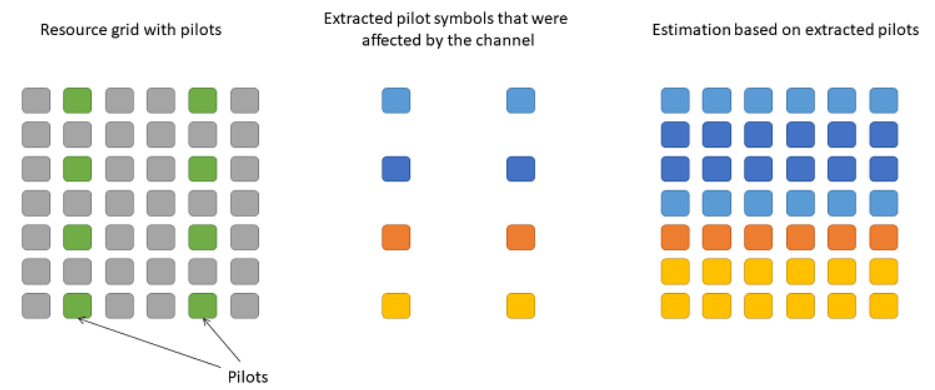

     Using the trained CNN, channel estimation is performed in single-input single-output (SISO) mode, utilizing the physical downlink shared channel (PDSCH) demodulation reference signal (DM-RS).

**Neural Network Training**

Neural network training consists of these steps:

- Data generation

- Splitting the generated data into training and validation sets

- Defining the CNN architecture

- Specifying the training options, optimizer, and learning rate

- Training the network

Training can be enabled  by setting `trainModel` to true.

trainModel = false; %

Data generation is set to produce 256 training examples or training data sets. This amount of data is sufficient to train a functional channel estimation network on a CPU in a reasonable time. For comparison, the pretrained model is based on 16,384 training examples.

Training data of the CNN model has a fixed size dimensionality, the network can only accept 612-by-14-by-1 grids, i.e. 612 subcarriers, 14 OFDM symbols and 1 antenna. Therefore, the model can only operate on a fixed bandwidth allocation, cyclic prefix length, and a single receive antenna.

The CNN treats the resource grids as 2-D images, hence each element of the grid must be a real number. In a channel estimation scenario, the resource grids have complex data. Therefore, the real and imaginary parts of these grids are input separately to the CNN.  

Note that Channel Estimator CNN is only trained for the values below:

    DelaySpread values between  1e-9 to 3e-7, 

    DelayProfiles 'TDL-A', 'TDL-B', 'TDL-C', 'TDL-D' and 'TDL-E' are used, 

    SNR values between  1 to 10 in dB, 

    MaximumDopplerShift values between 5 to 400 in Hz.

% Set the random seed for reproducibility
rng(42)
if trainModel
    
    [trainData,trainLabels] = hGenerateTrainingData(256);           % Generates the training data
    
    batchSize = 32;                                                 % Number of examples per mini-batch
    
    trainData = cat(4,trainData(:,:,1,:),trainData(:,:,2,:));       % Split real and imaginary grids into 2 image sets, then concatenate
    trainLabels = cat(4,trainLabels(:,:,1,:),trainLabels(:,:,2,:));

    
    valData = trainData(:,:,:,1:batchSize);                         % Split into training and validation sets
    valLabels = trainLabels(:,:,:,1:batchSize);

    trainData = trainData(:,:,:,batchSize+1:end);
    trainLabels = trainLabels(:,:,:,batchSize+1:end);

    valFrequency = round(size(trainData,4)/batchSize/5);            % Validate roughly 5 times every epoch

    % CNN structure
    layers = [ ...
        imageInputLayer([612 14 1],'Normalization','none')
        convolution2dLayer(9,64,'Padding',4)
        reluLayer
        convolution2dLayer(5,64,'Padding',2,'NumChannels',64)
        reluLayer
        convolution2dLayer(5,64,'Padding',2,'NumChannels',64)
        reluLayer
        convolution2dLayer(5,32,'Padding',2,'NumChannels',64)
        reluLayer
        convolution2dLayer(5,1,'Padding',2,'NumChannels',32)
        regressionLayer
    ];

    % Training policy
    options = trainingOptions('adam', ...
        'InitialLearnRate',3e-4, ...
        'MaxEpochs',5, ...
        'Shuffle','every-epoch', ...
        'Verbose',false, ...
        'Plots','training-progress', ...
        'MiniBatchSize',batchSize, ...
        'ValidationData',{valData, valLabels}, ...
        'ValidationFrequency',valFrequency, ...
        'ValidationPatience',5);

    % Train the network
    [channelEstimationCNN,trainingInfo] = trainNetwork(trainData, ...
        trainLabels,layers,options);
else
    load('trainedChannelEstimationNetwork.mat') % Load pretrained network if trainModel is set to false
end

The CNN has 5 convolutional layers. The input layer expects matrices of size 612-by-14 (612 is the number of subcarriers and 14 is the number of OFDM symbols).

channelEstimationCNN.Layers

ans =   11×1 Layer array with layers:

     1   'imageinput'         Image Input         612×14×1 images
     2   'conv_1'             Convolution         64 9×9×1 convolutions with stride [1  1] and padding [4  4  4  4]
     3   'relu_1'             ReLU                ReLU
     4   'conv_2'             Convolution         64 5×5×64 convolutions with stride [1  1] and padding [2  2  2  2]
     5   'relu_2'             ReLU                ReLU
     6   'conv_3'             Convolution         64 5×5×64 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu_3'             ReLU                ReLU
     8   'conv_4'             Convolution         32 5×5×64 convolutions with stride [1  1] and padding [2  2  2  2]
     9   'relu_4'             ReLU                ReLU
    10   'conv_5'             Convolution         1 5×5×32 convolutions with stride [1  1] and padding [2  2  2  2]
    11   'regre

# **Create Channel Model for Simulation**

Load the predefined simulation parameters, including the PDSCH parameters and DM-RS configuration. The returned object |carrier| is a valid carrier configuration object and |pdsch| is a PDSCH configuration, structure set for a SISO transmission.

SNRdB = 10; %in dB
[gnb,carrier,pdsch] = hDeepLearningChanEstSimParameters();

Create a TDL channel model and set channel parameters. TDL models 'A' and 'E' will be compared, TDL-A is constructed to represent channel profile for NLOS while TDL-E is constructed for LOS. 

`'TDL-A' and'TDL-E'` — These values correspond to the delay profiles defined in TR 38.901 Section 7.7.2, Tables 7.7.2-1 and 7.7.2-5.

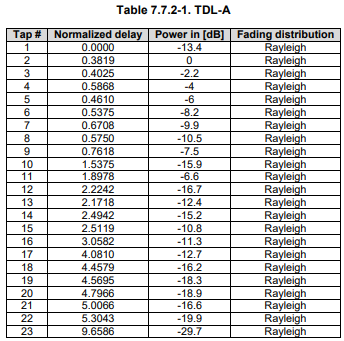 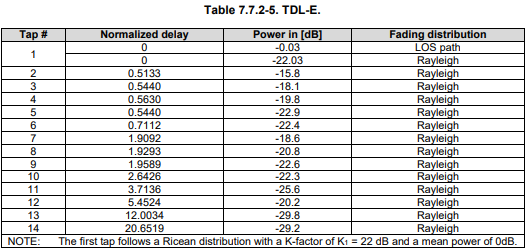

% Create a TDL channel model and set channel parameters. Later TDL-E will be used for comparison between LOS and NLOS channels.
channel = nrTDLChannel;
channel.Seed = 0;
channel.DelayProfile = 'TDL-A';
channel.DelaySpread = 3e-7;
channel.MaximumDopplerShift = 50;
% SISO configuration (Estimator CNN is trained only for SISO)
channel.NumTransmitAntennas = 1;
channel.NumReceiveAntennas = 1;
waveformInfo = nrOFDMInfo(carrier);
channel.SampleRate = waveformInfo.SampleRate;

Get the maximum number of delayed samples by a channel multipath component. This number is calculated from the channel path with the largest delay and the implementation delay of the channel filter. This number is needed to flush the channel filter when obtaining the received signal.

chInfo = info(channel);
maxChDelay = ceil(max(chInfo.PathDelays*channel.SampleRate))+chInfo.ChannelFilterDelay;

# **Simulate PDSCH DM-RS Transmission**

Simulate a PDSCH DM-RS transmission by performing these steps:

- Generate the resource grid

- Insert DM-RS symbols

- Perform OFDM modulation

- Send modulated waveform through the channel model

- Add white Gaussian noise

- Perform perfect timing synchronization

- Perform OFDM demodulation

The DM-RS symbols in the grid are used for channel estimation. This example does not transmit any data, therefore, the resource grid does not include any PDSCH symbols.

[~,dmrsIndices,dmrsSymbols,pdschIndicesInfo] = hPDSCHResources(gnb,pdsch); % Generate DM-RS indices and symbols
pdschGrid = nrResourceGrid(carrier); % Create PDSCH resource grid
pdschGrid(dmrsIndices) = pdschGrid(dmrsIndices)+dmrsSymbols; % Map PDSCH DM-RS symbols to the grid
txWaveform = nrOFDMModulate(carrier,pdschGrid); % OFDM-modulate associated resource elements

Visualize DM-RS Time-Frequency Locations

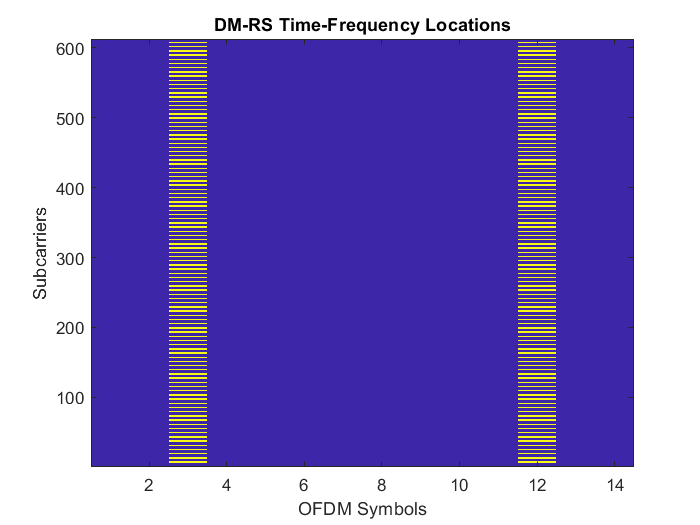

% Map the DM-RS symbols to the grid with the help of DM-RS indices
grid = zeros([12*carrier.NSizeGrid carrier.SymbolsPerSlot pdsch.NLayers]);
grid(dmrsIndices) = dmrsSymbols;
figure
imagesc(abs(grid(:,:,1)));
axis xy;
xlabel('OFDM Symbols');
ylabel('Subcarriers');
title('DM-RS Time-Frequency Locations');

To flush the channel content, append zeros at the end of the transmitted waveform. These zeros take into account any delay introduced in the channel, such as multipath and implementation delay. The number of zeros depends on the sampling rate, delay profile, and delay spread. Then Send data through the TDL channel model.

txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))]; 
[rxWaveform,pathGains,sampleTimes] = channel(txWaveform); % Transmit data through the channel.

Add additive white Gaussian noise (AWGN) to the received time-domain waveform. To take into account sampling rate, normalize the noise power. The SNR is defined per resource element (RE) for each receive antenna (3GPP TS 38.101-4).

SNR = 10^(SNRdB/20); 
N0 = 1/(sqrt(2.0*gnb.NRxAnts*double(waveformInfo.Nfft))*SNR); 
noise = N0*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
rxWaveform = rxWaveform + noise;

Perform perfect synchronization. To find the strongest multipath component, use the information provided by the channel.

pathFilters = getPathFilters(channel); % Get path filters for perfect channel estimation
[offset,~] = nrPerfectTimingEstimate(pathGains,pathFilters);
rxWaveform = rxWaveform(1+offset:end, :);

OFDM-demodulate the received data to recreate the resource grid.

rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
[K,L,R] = size(rxGrid); % Padding the grid with zeros in case an incomplete slot has been demodulated
if (L < carrier.SymbolsPerSlot)
    rxGrid = cat(2,rxGrid,zeros(K,carrier.SymbolsPerSlot-L,R));
end

# **Compare and Visualize Various Channel Estimations**

Now practical and neural network estimations of the same channel model will be compared.

estChannelGridPerfect = nrPerfectChannelEstimate(carrier,pathGains, pathFilters,offset,sampleTimes);
[estChannelGrid,~] = nrChannelEstimate(carrier,rxGrid,dmrsIndices, dmrsSymbols,'CDMLengths',pdschIndicesInfo.CDMLengths);

To perform channel estimation using the neural network, we must interpolate the received grid. Then split the interpolated image into its real and imaginary parts and input these images together into the neural network as a single batch. Finally, concatenate and transform the results back into complex data.

% Interpolate the received resource grid using pilot symbol locations
interpChannelGrid = hPreprocessInput(rxGrid,dmrsIndices,dmrsSymbols);

% Concatenate the real and imaginary grids along the batch dimension
nnInput = cat(4,real(interpChannelGrid),imag(interpChannelGrid));

% Use the neural network to estimate the channel
estChannelGridNN = predict(channelEstimationCNN,nnInput);

% Convert results to complex 
estChannelGridNN = complex(estChannelGridNN(:,:,:,1),estChannelGridNN(:,:,:,2));

Calculate the mean squared error (MSE) of each estimation method.

% Calculate the mean squared error (MSE) of each estimation method.
neural_mse = mean(abs(estChannelGridPerfect(:) - estChannelGridNN(:)).^2);
interp_mse = mean(abs(estChannelGridPerfect(:) - interpChannelGrid(:)).^2);
practical_mse = mean(abs(estChannelGridPerfect(:) - estChannelGrid(:)).^2);

Plot the individual channel estimations and the actual channel realization obtained from the channel filter taps. 

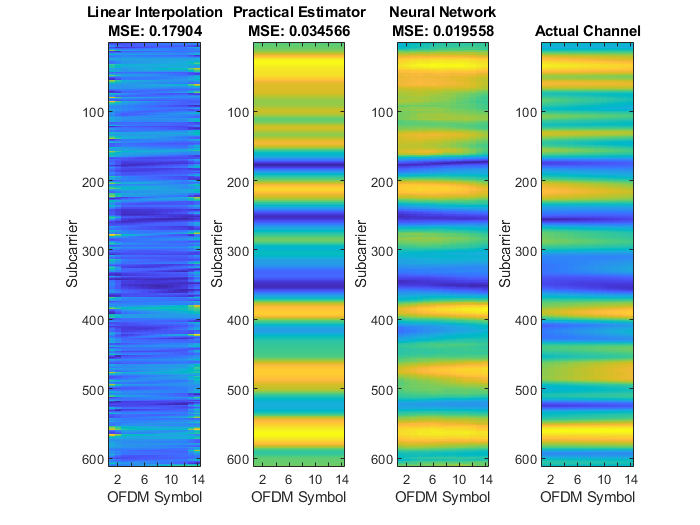

plotChEstimates(interpChannelGrid,estChannelGrid,estChannelGridNN,estChannelGridPerfect,interp_mse,practical_mse,neural_mse);

We can compare the estimator at different SNR values

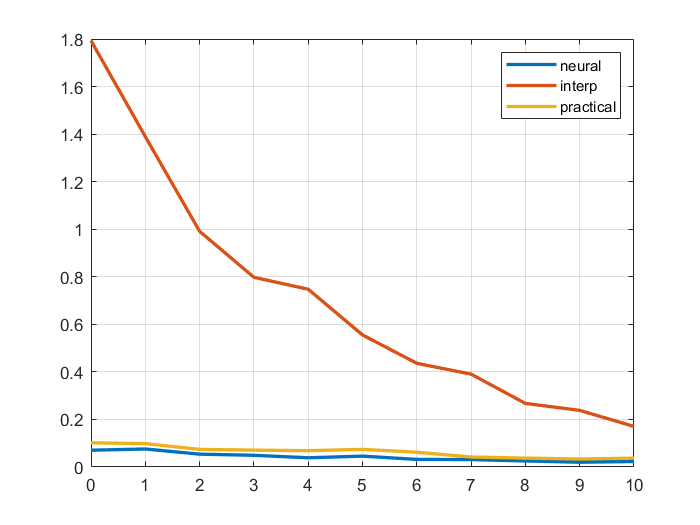

SNRdB =  0:1:10;
SNR = 10.^(SNRdB./20); 
DelayProfile = 'TDL-A';
DelaySpread = 3e-7;
MaximumDopplerShift = 50;
CNN = channelEstimationCNN;
SNR_lin = SNR;
[neural_mse_arr,interp_mse_arr,practical_mse_arr,estChannelGridPerfect] = MSE_of_estimators(DelayProfile,DelaySpread,MaximumDopplerShift,CNN,SNR_lin);
clf;
plot(SNRdB,[neural_mse_arr interp_mse_arr practical_mse_arr], 'Linewidth', 2);
grid on;
legend('neural', 'interp','practical', 'Location', 'Northeast');
xlim([0, 10]);

Since both the practical estimator and the neural network estimator outperform linear interpolation, let's compare these two.

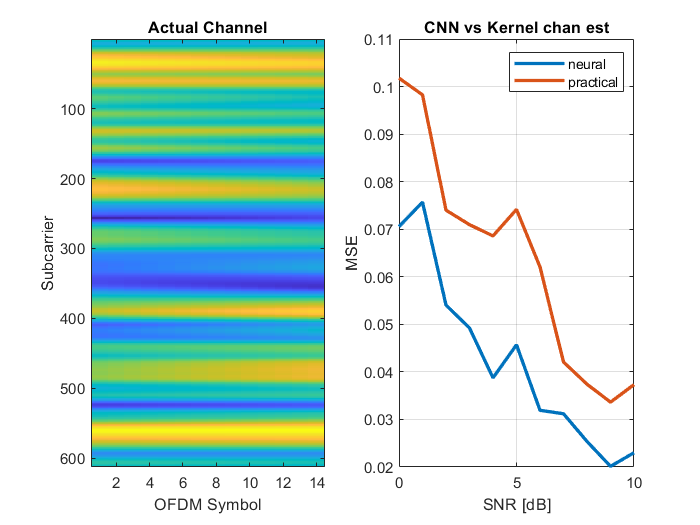

plotneuralvspractival(estChannelGridPerfect,SNRdB,neural_mse_arr, practical_mse_arr);

For delay profile  'TDL-A' (NLOS), CNN performs better than kernel estimation.

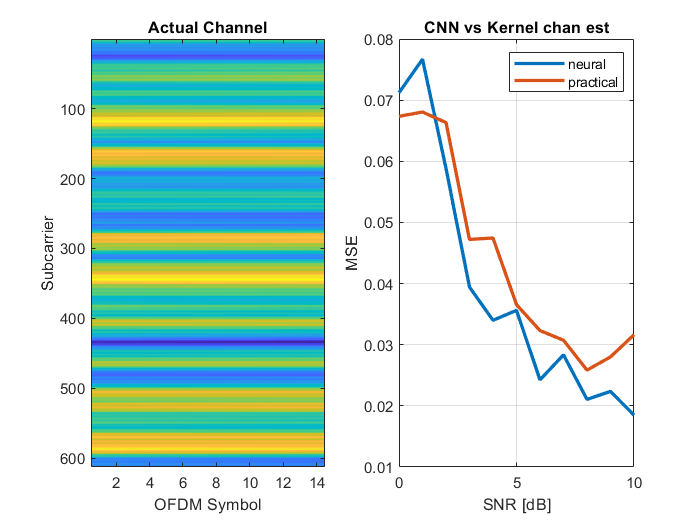

DelayProfile = 'TDL-E'; %Previously DelayProfile was set to 'TDL-A'
[neural_mse_arr,~,practical_mse_arr,estChannelGridPerfect] = MSE_of_estimators(DelayProfile,DelaySpread,MaximumDopplerShift,CNN,SNR_lin);
plotneuralvspractival(estChannelGridPerfect,SNRdB,neural_mse_arr, practical_mse_arr);

For delay profile  'TDL-E' (LOS), CNN performs little better than kernel estimation for SNR levels higher than 2 dB.

**Higher doppler shift + TDL-A (NLOS) Delay Profile Channel**

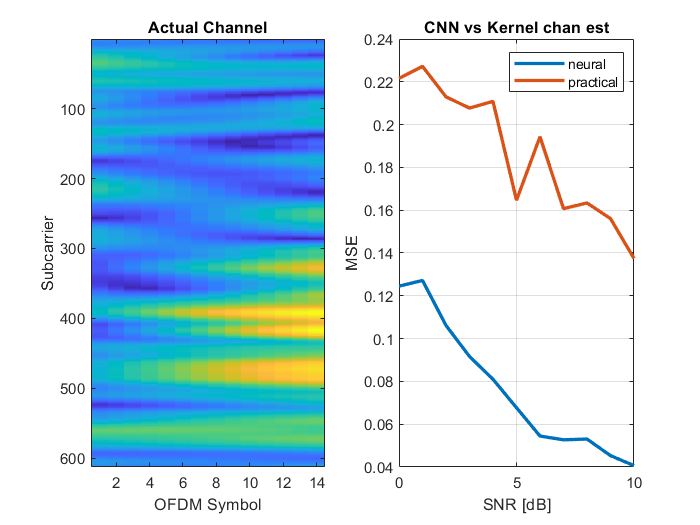

MaximumDopplerShift = 400; %Previously MaximumDopplerShift was set to 50
DelayProfile = 'TDL-A';
[neural_mse_arr,~,practical_mse_arr,estChannelGridPerfect] = MSE_of_estimators(DelayProfile,DelaySpread,MaximumDopplerShift,CNN,SNR_lin);
plotneuralvspractival(estChannelGridPerfect,SNRdB,neural_mse_arr, practical_mse_arr);

**Higher doppler shift + TDL-E (LOS) Delay Profile Channel**

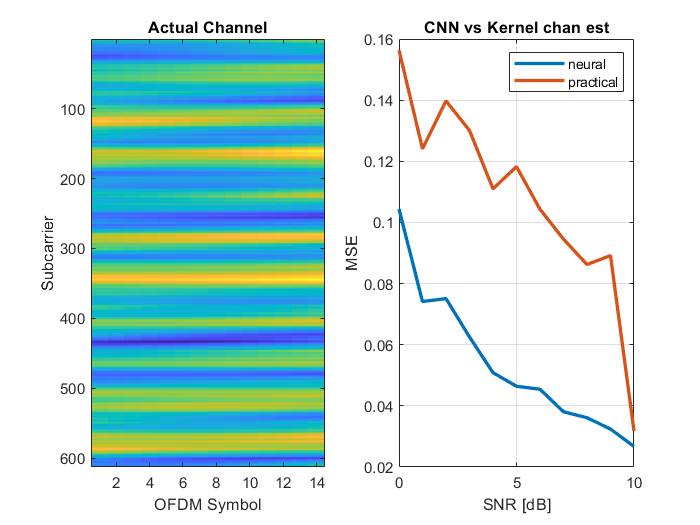

MaximumDopplerShift = 400; %Previously MaximumDopplerShift was set to 50
DelayProfile = 'TDL-E'; %Previously MaximumDopplerShift was set to 50
[neural_mse_arr,interp_mse_arr,practical_mse_arr,estChannelGridPerfect] = MSE_of_estimators(DelayProfile,DelaySpread,MaximumDopplerShift,CNN,SNR_lin);
plotneuralvspractival(estChannelGridPerfect,SNRdB,neural_mse_arr, practical_mse_arr);

## **Conclusion (Part - 1)**

    As it shown in the figures above, a basic pre-trained CNN outperforms traditional channel estimation methods for various channel types. Therefore results show the power of the CNN when it comes to classification and CNNs can definitely be used for channel estimation if they are trained well. The drawback to using the CNN model may be the high number of weights that is used, and model weights has to be kept in the memory all the time.

# 2 - NR Phase Noise Modeling and Compensation

    In 5G NR, 3GPP introduces a new reference signal, named phase tracking reference signal (PT-RS), to deal with oscillator noise. The noise incurred in the oscillators results in phase modulation of the information signal, leading to significant changes in the frequency spectrum and timing properties of the information signal. This phenomenon related to oscillators is called phase noise. Phase noise produced in local oscillators introduces a significant degradation at millimeter wave (mmWave) frequencies (including 5g FR2 bands), depending on the power spectral density of phase noise. Phase noise leads to common phase error (CPE) and intercarrier interference (ICI). CPE leads to an identical rotation of a received symbol in each subcarrier. ICI leads to a loss of orthogonality between the subcarriers. Due to the distributed structure of PT-RS in frequency domain, the example primarily uses PT-RS to estimate and minimize the effect of CPE on system performance. The example applies phase noise on the waveform consisting of physical downlink shared channel (PDSCH) and shows the change in error vector magnitude (EVM) and bit error rate (BER) with and without CPE compensation. This figure shows the processing chain implemented in this example.

##                      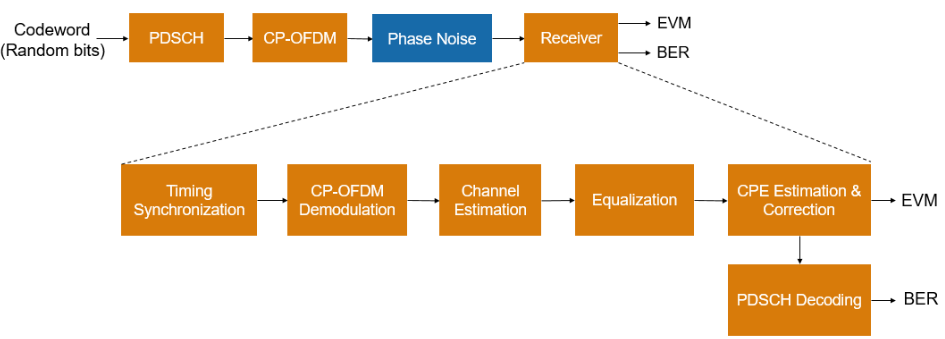

**                                                                                                                        Figure 2.1**

    An oscillator is an autonomous electronic circuit, which ideally produces a periodic, oscillating electric signal at a precise frequency. This frequency is commonly used to provide clock signals for timing and frequency synchronization, and carrier signals for passband transmission and reception in communication systems. Oscillators used in communication transceivers are imperfect, in that their output signals are affected by random amplitude and phase instabilities. The signal at the output is written as:

                                                                                    v(t) = (1 + a(t)) cos(2π * fosc * t + θ(t)),

where fosc is the center frequency of the oscillator, a(t) represents the random amplitude variations, and θ(t) denotes the random phase variations. In the time domain, the instabilities manifest as a random jitter in the zero-crossings of the desired signal as shown in Fig. 2.2 (a). In the frequency domain, a spectrum of noise around fosc appears as shown in Fig. 2.2 (b). The amplitude perturbations are typically attenuated by a limiting mechanism in the oscillator circuitry, and hence can be ignored [10]. Phase noise in the signal from the oscillators is the focus of this part of the work.

                                                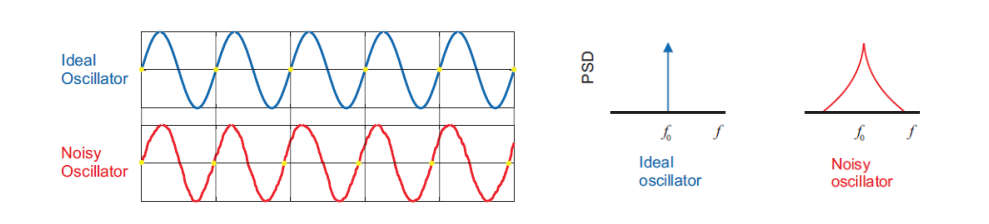

                                                                                **Figure 2.2**: Signal output of an oscillator: (a) Time-domain signal, (b) Power spread in the frequency domain. 

As an example, let us now visualize in Fig. 2.3 the effect of the Gaussian phase error on a 16-QAM constellation, where the signal-to-noise (SNR) per bit is 30 dB, and the innovation variance^2 is set to σ 2 ∆ = 10−4 rad2. 

During the simulation, We should expect to see similar change(distortion) on the constellation diagrams due to phase phase errors.

                                                                                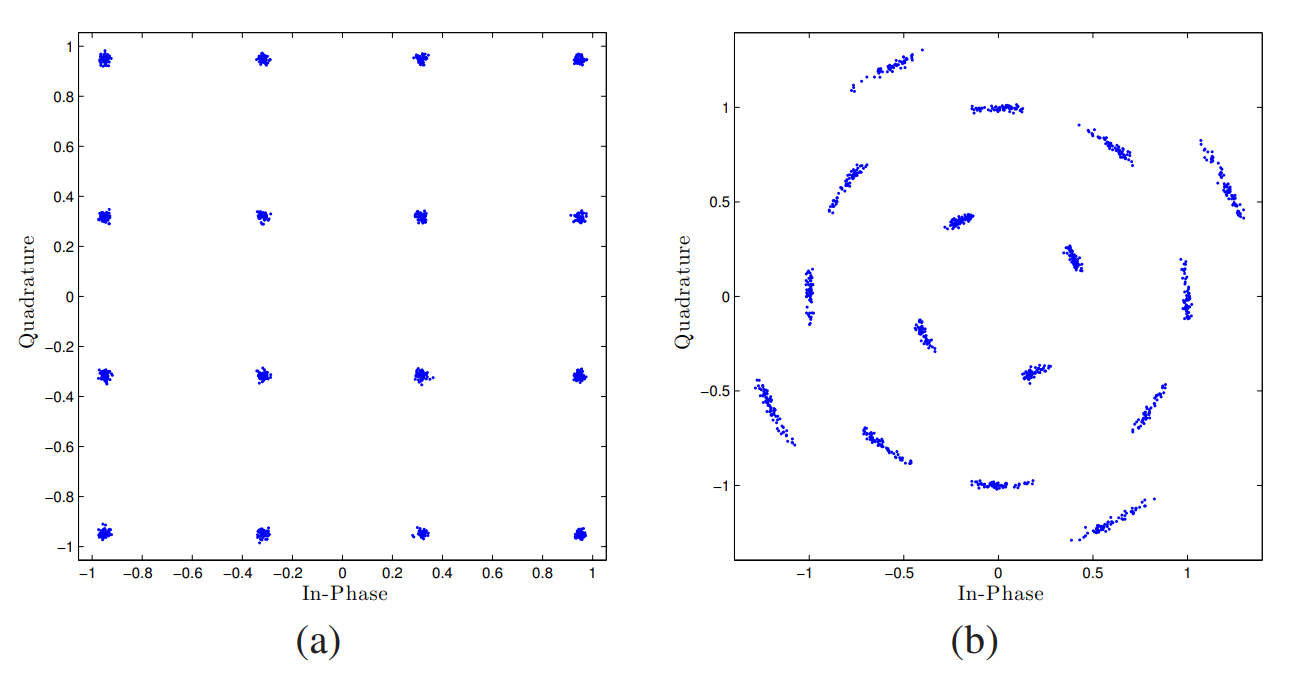

**Figure 2.3**: 16-QAM constellation at SNR per bit of 30 dB, when (a) no phase noise is present, and when (b) the signal is affected by the Wiener phase noise process with innovation variance σ 2 ∆ = 1 × 10−4 rad2 .

# **Phase Noise Modeling**

    The oscillator power spectral density models the phase noise. This example uses a multipole zero model to approximate the power spectral density of the oscillator. Phase nois model 'C' is used in this work which is obtained from the practical oscillator operating at 29.55 GHz, as described in TR 38.803 Section 6.1.10. The example uses a carrier with a subcarrier spacing of 60 kHz for a transmission bandwidth of 50 MHz.

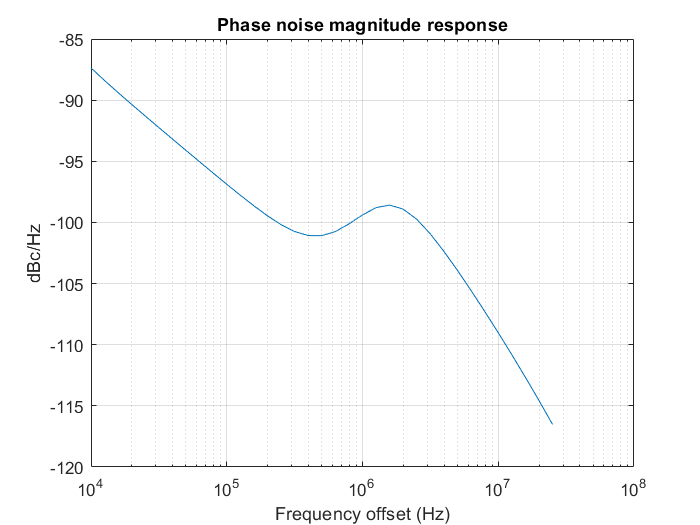

clear all
% But First Configure carrier, as we need the params for the PN Modeling
carrier                   = nrCarrierConfig;
carrier.SubcarrierSpacing = 60; % KHz
carrier.CyclicPrefix      = 'normal';
carrier.NSizeGrid         = 66;

% Set the operating frequency and choose the phase noise model
simParameters.Fc      = 29.55e9; % Frequency in Hz
simParameters.PNModel = 'C';     % % 'A' (TDoc R1-163984 Set A), 'B' (TDoc R1-163984 Set B), 'C' (TR 38.803)

% Get the sample rate
waveformConfig = nrOFDMInfo(carrier);
sr             = waveformConfig.SampleRate;

% Phase noise level
foffsetLog = (4:0.1:log10(sr/2));    % Model offset from 1e4 Hz to sr/2 Hz
foffset    = 10.^foffsetLog;         % Linear frequency offset
pn_PSD     = PNF(foffset,simParameters.Fc);  % dBc/Hz

% Set phase noise level
pnoise = comm.PhaseNoise('FrequencyOffset',foffset,'Level',pn_PSD,'SampleRate',sr);
pnoise.RandomStream = "mt19937ar with seed";

% Visualize spectrum mask of phase noise
figure 
semilogx(foffset,pn_PSD)
xlabel('Frequency offset (Hz)')
ylabel('dBc/Hz')
title('Phase noise magnitude response')
grid on;

# **PDSCH Configuration**

The example configures PDSCH occupying the complete carrier with modulation scheme set to '64QAM' and number of layers set to 1. The example defaults to a single layer and a single codeword of random uncoded bits.

% Set PDSCH parameters
pdsch                  = nrPDSCHConfig;
pdsch.PRBSet           = 0:carrier.NSizeGrid-1;
pdsch.SymbolAllocation = [0 14];
pdsch.Modulation       = '64QAM';
pdsch.NumLayers        = 1;
pdsch.MappingType      = 'A';
pdsch.NID              = 1;
pdsch.RNTI             = 2;

% Set DM-RS parameters
pdsch.DMRS.DMRSConfigurationType   = 1;
pdsch.DMRS.DMRSTypeAPosition       = 2;
pdsch.DMRS.DMRSAdditionalPosition  = 0;
pdsch.DMRS.DMRSLength              = 1;
pdsch.DMRS.DMRSPortSet             = [];
pdsch.DMRS.NumCDMGroupsWithoutData = 1;
pdsch.DMRS.NIDNSCID                = 1;
pdsch.DMRS.NSCID                   = 0;

% Set PT-RS parameters
pdsch.EnablePTRS                   = 1;
pdsch.PTRS.TimeDensity             = 1;
pdsch.PTRS.FrequencyDensity        = 2;
pdsch.PTRS.REOffset                = '00';
pdsch.PTRS.PTRSPortSet             = [];

# **Generate the Waveform**

The waveform is generated for 2 frames and the field `NumFrames` of `simParameters` structure controls the number of frames of the waveform. The steps involved are (2):

- Generate random codeword with the bit capacity of PDSCH

- Get the PDSCH symbols for the random codeword and map them to grid

- Generate and map DM-RS symbols to grid

- Generate and map PT-RS symbols to grid

- Perform OFDM modulation for the complete grid of all frames

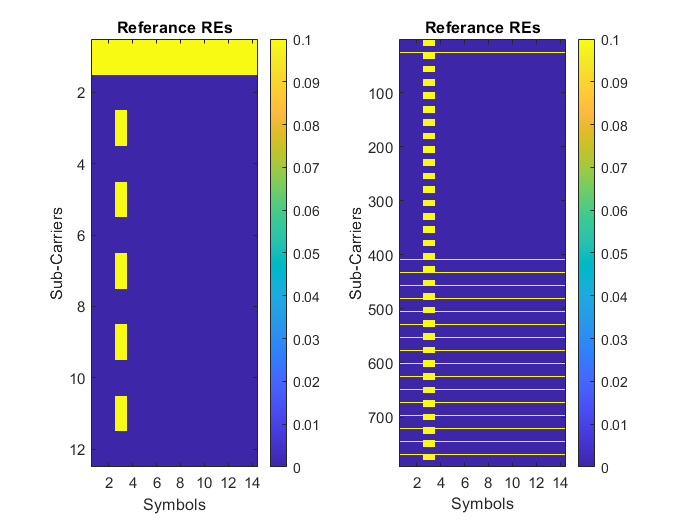

% Number of frames to generate the waveform
simParameters.NumFrames = 2;

% Get the number of slots in the waveform and number of symbols in a slot
numSlots = carrier.SlotsPerFrame*simParameters.NumFrames;
nSlotSymb = carrier.SymbolsPerSlot;

% Initialize the grid for specified number of frames
txGrid = zeros(carrier.NSizeGrid*12,nSlotSymb*numSlots,pdsch.NumLayers);
txGrid_ref = txGrid;

% Processing loop
txbits = [];
rng('default')
for slotIdx = 0:numSlots - 1
    % Set slot number
    carrier.NSlot = slotIdx;

    % Get PDSCH indices and structural information
    [pdschInd,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);

    % Generate random codeword(s)
    numCW = pdsch.NumCodewords; % Number of codewords
    data = cell(1,numCW);
    for i = 1:numCW
        data{i} = randi([0 1],pdschIndicesInfo.G(i),1);
        txbits = [txbits; data{i}]; %#ok<AGROW>
    end

    % Get modulated symbols
    pdschSym = nrPDSCH(carrier,pdsch,data);

    % Get DM-RS symbols and indices
    dmrsSym = nrPDSCHDMRS       (carrier,pdsch);
    dmrsInd = nrPDSCHDMRSIndices(carrier,pdsch);

    % Get PT-RS symbols and indices
    ptrsSym = nrPDSCHPTRS(carrier,pdsch);
    ptrsInd = nrPDSCHPTRSIndices(carrier,pdsch);

    % Resource element mapping to slot grid
    slotGrid = nrResourceGrid(carrier,pdsch.NumLayers);
    slotGrid(dmrsInd)  = dmrsSym;
    slotGrid(ptrsInd)  = ptrsSym;
    slotGrid_ref = slotGrid;
    slotGrid(pdschInd) = pdschSym;

    % Generate txGrid for all frames by mapping slotGrid at respective locations
    txGrid(:,slotIdx*nSlotSymb+1:(slotIdx+1)*(nSlotSymb),:) = slotGrid;
    txGrid_ref(:,slotIdx*nSlotSymb+1:(slotIdx+1)*(nSlotSymb),:) = slotGrid_ref;
end
% Plot Referance Signal Locations on a slot
colorrange =[0,0.1];figure();clf; % To make the effect of changes visible
subplot(1,2,1); imagesc(abs(slotGrid_ref(1:12,end-14+1:end)),colorrange); colorbar();
title("Referance REs"); xlabel("Symbols"); ylabel("Sub-Carriers")
subplot(1,2,2); imagesc(abs(slotGrid_ref(:   ,end-14+1:end)),colorrange); colorbar();
title("Referance REs"); xlabel("Symbols"); ylabel("Sub-Carriers")

% Performing OFDM modulation
carrier.NSlot = 0; % Reset the slot number to 0 for OFDM modulation
txWaveform        = nrOFDMModulate(carrier,txGrid);
txWaveform_ref = nrOFDMModulate(carrier,txGrid_ref);

# **Observe the Phase Noise effects**

Below I will simulate and plot: Effect of the Phase Noise on one 5G NR OFDM resource element (RE)  without a propagation channel so there is also no timing synchronization, channel estimation, and equalization.

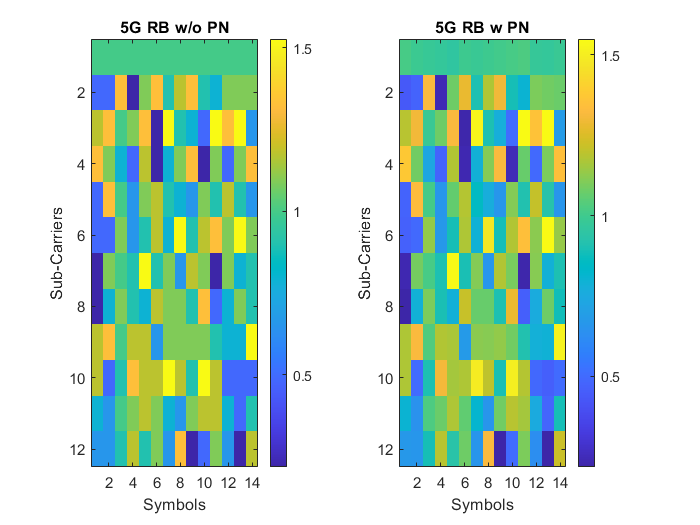

% Apply Phase Noise without channel disturbances to the frames populated with data

rxWaveform = zeros(size(txWaveform),'like',txWaveform);
for i = 1:size(txWaveform,2)
    rxWaveform(:,i) = pnoise(txWaveform(:,i));
    release(pnoise)
end

% Apply PN to the frames populated DM-RS PT-RS control signals
rxWaveform_ref = zeros(size(txWaveform_ref),'like',txWaveform_ref);
for i = 1:size(txWaveform_ref,2)
    rxWaveform_ref(:,i) = pnoise(txWaveform_ref(:,i));
    release(pnoise)
end

% Demodulate the Signal

rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
figure(); clf; 
subplot(1,2,1);imagesc(abs(txGrid(1:12,end-14+1:end))); colorbar();
title ("5G RB w/o PN"); xlabel("Symbols"); ylabel("Sub-Carriers")
subplot(1,2,2);imagesc(abs(rxGrid(1:12,end-14+1:end))); colorbar();
title ("5G RB w PN"); xlabel("Symbols"); ylabel("Sub-Carriers")

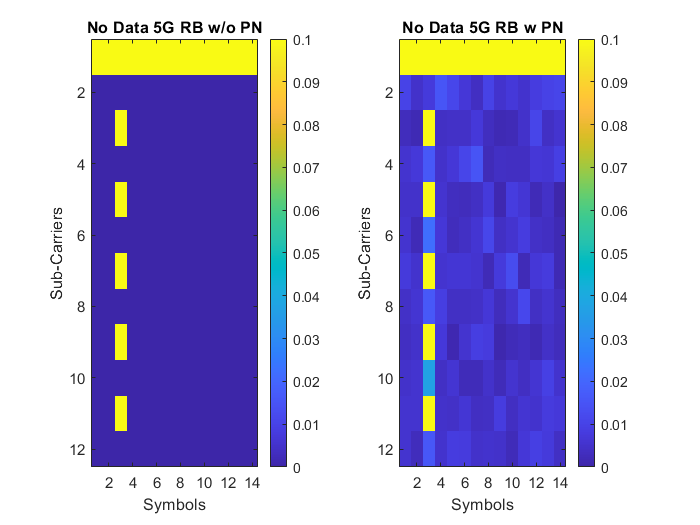

% Let's see the PN effect with Only Referance signals to vizualize it easily
rxGrid_nodata = nrOFDMDemodulate(carrier,rxWaveform_ref);
figure(); clf; 
subplot(1,2,1); imagesc(abs(slotGrid_ref(1:12,end-14+1:end)),colorrange); colorbar();
title ("No Data 5G RB w/o PN"); xlabel("Symbols"); ylabel("Sub-Carriers")
subplot(1,2,2); imagesc(abs(rxGrid_nodata  (1:12,end-14+1:end)),colorrange); colorbar();
title ("No Data 5G RB w PN"); xlabel("Symbols"); ylabel("Sub-Carriers")

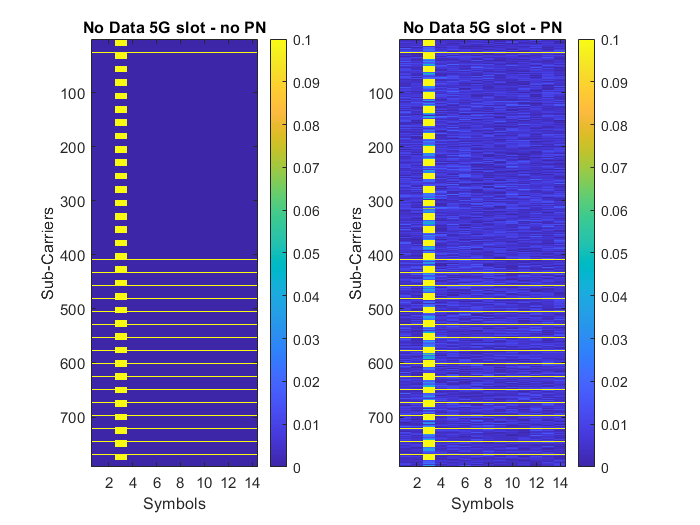

% NOW PN effect on a full slot
figure(); clf; 
subplot(1,2,1); imagesc(abs(slotGrid_ref(:,end-14+1:end)), colorrange); colorbar();
title ("No Data 5G slot - no PN"); xlabel("Symbols"); ylabel("Sub-Carriers")
subplot(1,2,2); imagesc(abs(rxGrid_nodata  (:,end-14+1:end)), colorrange); colorbar();
title ("No Data 5G slot - PN"); xlabel("Symbols"); ylabel("Sub-Carriers");

# **Observe CPE and CPE compansation effect**

Before returning the equalized PDSCH symbols and decoded bits, the receiver performs these steps:

- Timing synchronization

- OFDM demodulation

- Channel estimation

- Equalization

- CPE estimation and correction

- PDSCH decoding

    For the CPE estimation and correction step, the receiver uses the logical field `CompensateCPE` of the `simParameters` structure. Because the example does not use a propagation channel, the steps of timing synchronization, channel estimation, and equalization are not strictly necessary. However, these steps help investigate the phase noise effects if you introduce a channel.

The example shows the equalized constellation symbols, EVM, and bit error rate, with and without CPE compensation.

### **Without CPE Compensation**

To disable the CPE compensation, set the field `CompensateCPE` of `simParameters` structure to 0.

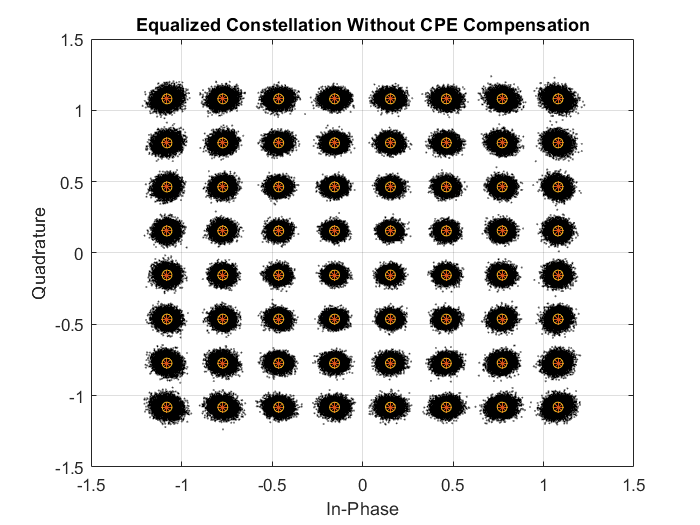

simParameters.CompensateCPE = 0;
[eqSymbols,rxbits] = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
refSymbols         = GCP(pdsch); % get constellation points
% Display the constellation diagram
figure
plot(eqSymbols,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Constellation Without CPE Compensation')
grid on
xlabel('In-Phase')
ylabel('Quadrature')

% Display RMS EVM
evm = comm.EVM('ReferenceSignalSource','Estimated from reference constellation','ReferenceConstellation',refSymbols);
fprintf('RMS EVM (in percent) for equalized symbols without CPE compensation: %f%% \n',evm(eqSymbols));

RMS EVM (in percent) for equalized symbols without CPE compensation: 4.062448% 


% Display bit error rate
errorRate = nnz(rxbits-txbits)/numel(txbits);
fprintf('Bit error rate without CPE compensation: %f \n',errorRate);

Bit error rate without CPE compensation: 0.000001 


### **With CPE Compensation**

To enable the CPE compensation, set the field `CompensateCPE` of `simParameters` structure to 0. Use PT-RS to estimate the CPE at all the OFDM symbol locations in a slot. Correct the CPE in the OFDM symbol locations within the range of PT-RS OFDM symbols.

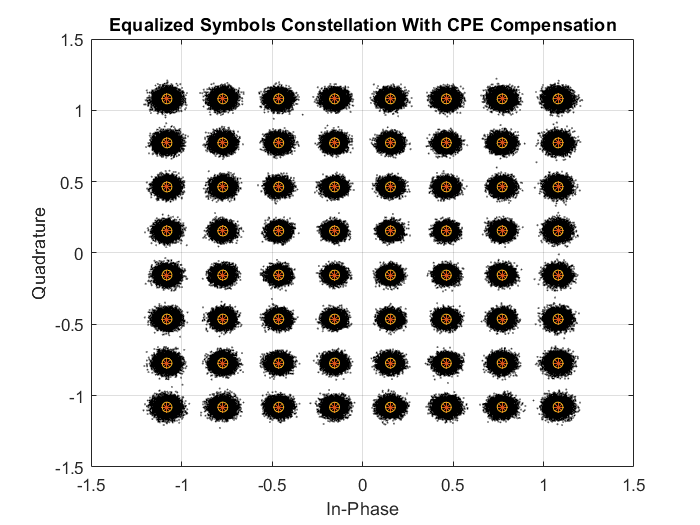

simParameters.CompensateCPE = 1;
[eqSymbolsCPE,rxbitsCPE] = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
% Display the constellation diagram
figure
plot(eqSymbolsCPE,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Symbols Constellation With CPE Compensation')
grid on
xlabel('In-Phase')
ylabel('Quadrature')

% Display RMS EVM
fprintf('RMS EVM (in percent) for equalized symbols with CPE compensation: %f%% \n',evm(eqSymbolsCPE))

RMS EVM (in percent) for equalized symbols with CPE compensation: 3.901497% 


% Display bit error rate
errorRateCPE = nnz(rxbitsCPE-txbits)/numel(txbits);
fprintf('Bit error rate with CPE compensation: %f \n',errorRateCPE)

Bit error rate with CPE compensation: 0.000000 


### Create The Channel

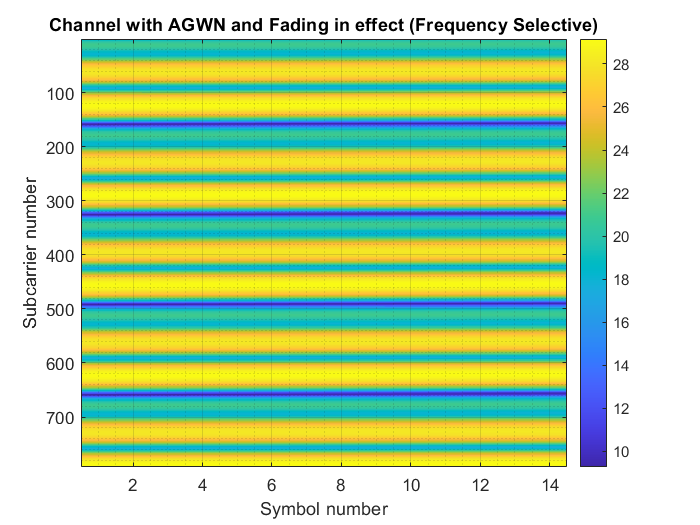

% This code from Prof. work
pathgain  = [-2 -3 -4]';          % in dB
pathdelay   = [0 2e-7 3e-7]';     % path delays in seconds
aoaAz = [15, 25, 35]';     
aoaEl = [0, 0, 0]';        
rxVel = [10,10,0]'; 
pathgain = mag2db(db2mag(pathgain)./ sum(db2mag(pathgain))); Etx = 1; EsN0Avg = 25;  
fdchan = FDChan(carrier, 'waveformConfig', waveformConfig, 'gain', pathgain, 'dly', pathdelay, 'aoaAz', aoaAz, 'aoaEl', aoaEl, 'rxVel', rxVel, 'Etx', Etx, 'EsN0Avg', EsN0Avg, 'fc', simParameters.Fc);
framenumber = 0; subframenumber = 0; slotnumber = 0;
len = waveformConfig.SymbolsPerSlot;
idx = framenumber * waveformConfig.SlotsPerSubframe*len + subframenumber * len + 1;
slotGrid = txGrid(:, idx:idx+len-1);
[~,chan,noiseVar] = fdchan.step(slotGrid, subframenumber, slotnumber);
chanSnr = 10*log10(abs(chan).^2/noiseVar);
figure(); clf; imagesc(chanSnr);
grid(gca,'minor'); grid on; colorbar();
xlabel('Symbol number'); ylabel('Subcarrier number'); title("Channel with AGWN and Fading in effect (Frequency Selective)");

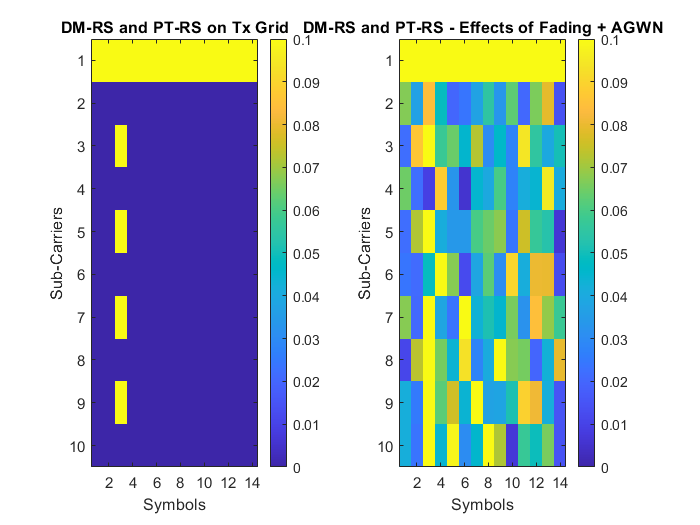

slotGrid = txGrid_ref(:, idx:idx+len-1);
[rxgrid,chan,noiseVar] = fdchan.step(slotGrid, subframenumber, slotnumber); 
figure(); clf; 
subplot(1,2,1); imagesc(abs(slotGrid_ref(1:10,end-14+1:end)),colorrange); colorbar();
title ("DM-RS and PT-RS on Tx Grid"); xlabel("Symbols"); ylabel("Sub-Carriers")
subplot(1,2,2); imagesc(abs(rxgrid(1:10,end-14+1:end)),colorrange); colorbar();
title ("DM-RS and PT-RS - Effects of Fading + AGWN"); xlabel("Symbols"); ylabel("Sub-Carriers")

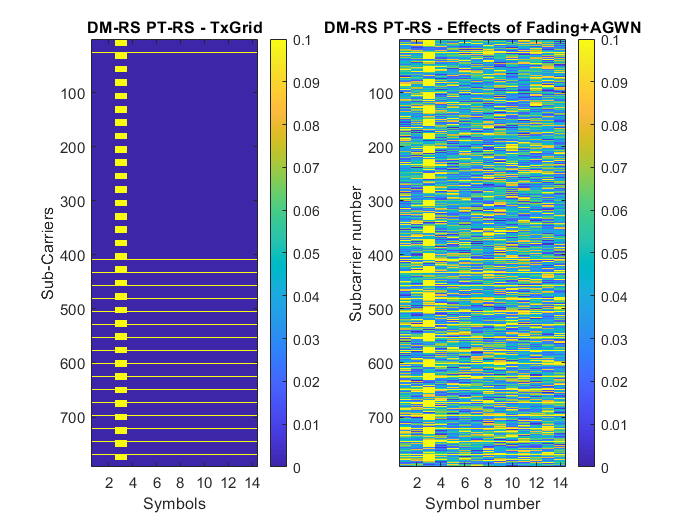

figure(); clf; 
subplot(1,2,1); imagesc(abs(slotGrid_ref(:,end-14+1:end)),colorrange); colorbar();
title ("DM-RS PT-RS - TxGrid"); xlabel("Symbols"); ylabel("Sub-Carriers")
subplot(1,2,2); imagesc(abs(rxgrid(:,end-14+1:end)),colorrange); colorbar();
title ("DM-RS PT-RS - Effects of Fading+AGWN"); xlabel("Symbols"); ylabel("Sub-Carriers")
colorbar();
xlabel('Symbol number');
ylabel('Subcarrier number');

### **Constellation with and without CPE Compensation without Phase Noise**

       We will see that even without phase noise added, AWGN with fading channel causes phase errors and CPE compensation helps to equaliize the Channel and highly improves overall performance. 

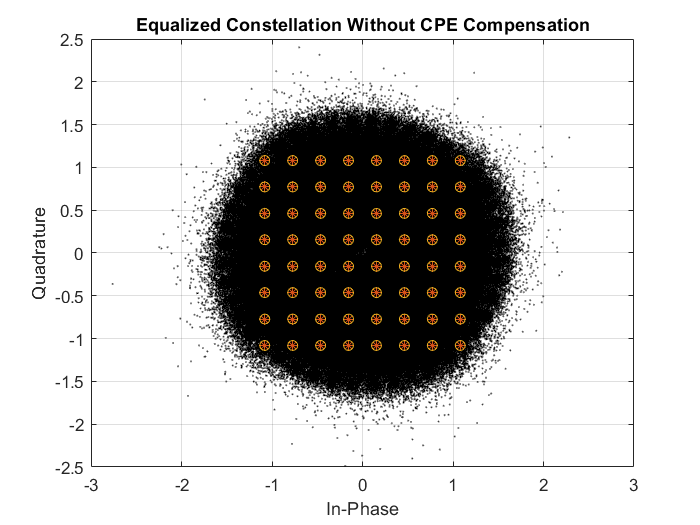

rxFdGrid = zeros(carrier.NSizeGrid*12,nSlotSymb*numSlots,pdsch.NumLayers);
nsym=1;
for fr = 1:simParameters.NumFrames
   for sub_fr = 1:10 
       for slot = 1:waveformConfig.SlotsPerSubframe
           len = waveformConfig.SymbolsPerSlot;
           %fprintf("fr=%d sub_fr=%2d slot=%d nsym=[%4d,%4d]\n",fr,sub_fr,slot,nsym,nsym+len-1)           
           slotGrid = txGrid(:, nsym:nsym+len-1);
           [rxSlot,chan,noiseVar] = fdchan.step(slotGrid, subframenumber, slotnumber); % 792x14 at a time
           rxFdGrid(:, nsym:nsym+len-1) = rxSlot;
           nsym=nsym+waveformConfig.SymbolsPerSlot;
       end
   end
end
rxFDWaveform = nrOFDMModulate(carrier,rxFdGrid);
simParameters.CompensateCPE = 0;
[eqSymbols,rxbits] = practicalReceiver(carrier,pdsch,simParameters,rxFDWaveform);
refSymbols         = GCP(pdsch); % get constellation points

% Plot the constellation diagram
figure
plot(eqSymbols,'k.', "MarkerSize", 1);
hold on;
plot(refSymbols,'*');
plot(refSymbols,'O');
title('Equalized Constellation Without CPE Compensation');
grid on;
xlabel('In-Phase');
ylabel('Quadrature');

% Display RMS EVM
evm = comm.EVM('ReferenceSignalSource', 'Estimated from reference constellation', 'ReferenceConstellation', refSymbols);
rms_evm_no_pn_wo_cpe = evm(eqSymbols);
fprintf('RMS EVM (in percent) eq symbols WITHOUT CPE compensation: %f%% \n', rms_evm_no_pn_wo_cpe);

RMS EVM (in percent) eq symbols WITHOUT CPE compensation: 16.187308% 


% Display bit error rate
errorRate_rms_evm_no_pn_wo_cpe = nnz(rxbits-txbits)/numel(txbits);
fprintf('Bit error rate WITHOUT CPE compensation: %f \n',errorRate_rms_evm_no_pn_wo_cpe);

Bit error rate WITHOUT CPE compensation: 0.308739 


To enable the CPE compensation, set the field `CompensateCPE` of `simParameters` structure to 0. Use PT-RS to estimate the CPE at all the OFDM symbol locations in a slot. Correct the CPE in the OFDM symbol locations within the range of PT-RS OFDM symbols.

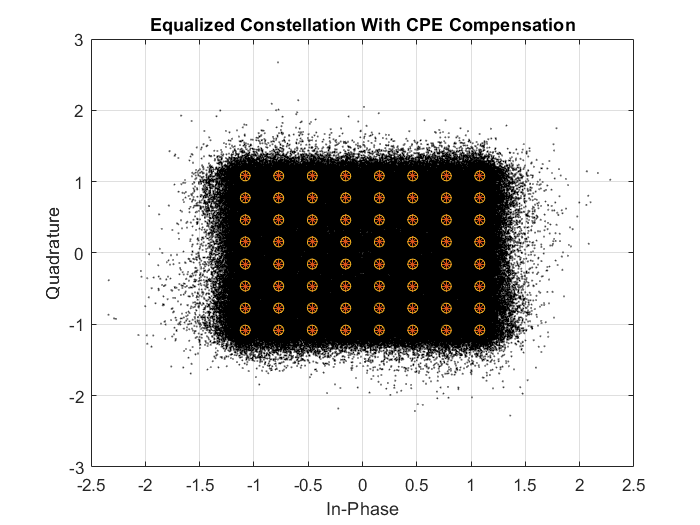

simParameters.CompensateCPE = 1;
[eqSymbolsCPE,rxbitsCPE] = practicalReceiver(carrier,pdsch,simParameters,rxFDWaveform);
% Display the constellation diagram
figure
plot(eqSymbolsCPE,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Constellation With CPE Compensation')
grid on
xlabel('In-Phase')
ylabel('Quadrature')

rms_evm_no_pn_w_cpe = evm(eqSymbolsCPE);
% Display RMS EVM
fprintf('RMS EVM (in percent) for equalized symbols WITH CPE compensation: %f%% \n',rms_evm_no_pn_w_cpe);

RMS EVM (in percent) for equalized symbols WITH CPE compensation: 10.023671% 


% Display bit error rate
errorRateCPE_rms_evm_no_pn_w_cpe = nnz(rxbitsCPE-txbits)/numel(txbits);
fprintf('Bit error rate WITH CPE compensation: %f \n',errorRateCPE_rms_evm_no_pn_w_cpe);

Bit error rate WITH CPE compensation: 0.027882 


### **Effect of CPE Compensation on Constellation with Phase Noise**

In this part, after Phase Noise added, CPE level increased but It is clear that CPE due to Phase Noise is much less than compared to the CPE due to radio channel. Simulations below shows that applying CPE compansation is crutial for decreasing phase error rate.

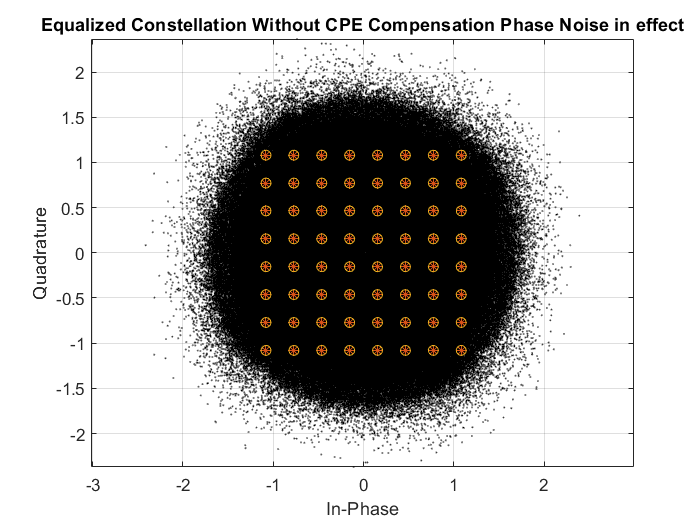

% Apply PN to the frames populated with data
rxWaveform = zeros(size(rxFDWaveform),'like',rxFDWaveform);
for i = 1:size(rxFDWaveform,2)
    rxWaveform(:,i) = pnoise(rxFDWaveform(:,i));
    release(pnoise)
end

simParameters.CompensateCPE = 0;
[eqSymbolsCPE,rxbitsCPE] = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
% Display the constellation diagram
figure
plot(eqSymbolsCPE,'k.', "MarkerSize", 1);
hold on;
plot(refSymbols,'*');
plot(refSymbols,'O');
title('Equalized Constellation Without CPE Compensation Phase Noise in effect');
grid on;
xlabel('In-Phase');
ylabel('Quadrature'); 
axis equal

% Display RMS EVM
rms_evm_w_pn_wo_cpe = evm(eqSymbolsCPE);
fprintf('RMS EVM (in percent) for equalized symbols WITHOUT CPE compensation: %f%% \n',rms_evm_w_pn_wo_cpe);

RMS EVM (in percent) for equalized symbols WITHOUT CPE compensation: 18.445351% 


% Display bit error rate
errorRateCPE_rms_evm_w_pn_wo_cpe = nnz(rxbitsCPE-txbits)/numel(txbits);
fprintf('Bit error rate WITHOUT CPE compensation: %f \n',errorRateCPE_rms_evm_w_pn_wo_cpe);

Bit error rate WITHOUT CPE compensation: 0.313119 


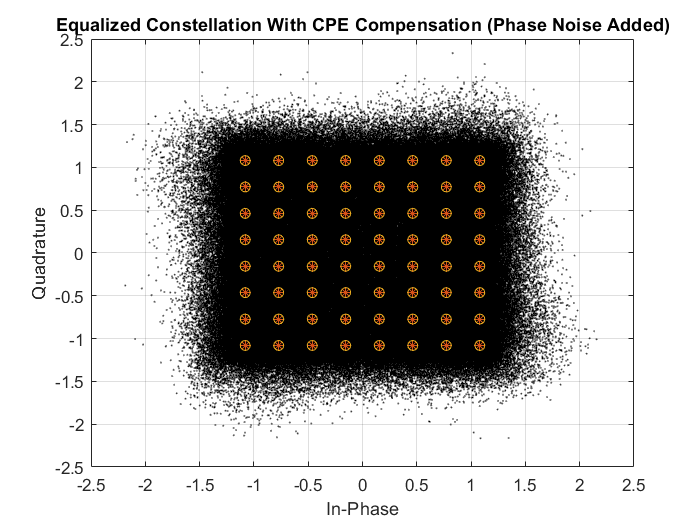


simParameters.CompensateCPE = 1;
[eqSymbols,rxbits] = practicalReceiver(carrier,pdsch,simParameters,rxWaveform);
refSymbols         = GCP(pdsch); % get constellation points
% Display the constellation diagram
figure
plot(eqSymbols,'k.', "MarkerSize", 1)
hold on
plot(refSymbols,'*')
plot(refSymbols,'O')
title('Equalized Constellation With CPE Compensation (Phase Noise Added)')
grid on
xlabel('In-Phase')
ylabel('Quadrature')


% Display RMS EVM (Error Vector Magnitude)
evm = comm.EVM('ReferenceSignalSource', 'Estimated from reference constellation', 'ReferenceConstellation', refSymbols);
rms_evm_w_pn_w_cpe = evm(eqSymbols);
fprintf('RMS EVM (in percent) eq symbols WITH CPE compensation: %f%% \n', rms_evm_w_pn_w_cpe);

RMS EVM (in percent) eq symbols WITH CPE compensation: 13.496581% 


% Display bit error rate
errorRate_rms_evm_w_pn_w_cpe = nnz(rxbits-txbits)/numel(txbits);
% BIT ERROR RATE IMPROVES SIGNIFICANTLY:
fprintf('Bit error rate WITH CPE compensation: %f \n',errorRate_rms_evm_w_pn_w_cpe);

Bit error rate WITH CPE compensation: 0.048885 


**Conclusions (Part 2)**

fprintf(['After Phase noise was added RMS EVM without CPE compansation increased from %f%% to %f%% \n and BER increased from %f to %f\n' ...
    'After Phase noise was added RMS EVM with CPE compansation increased from %f%% to %f%% \n and BER increased from %f to %f\n'],rms_evm_no_pn_wo_cpe, rms_evm_w_pn_wo_cpe, ...
    errorRate_rms_evm_no_pn_wo_cpe, errorRateCPE_rms_evm_w_pn_wo_cpe ...
    ,rms_evm_no_pn_w_cpe, rms_evm_w_pn_w_cpe, errorRateCPE_rms_evm_no_pn_w_cpe,errorRate_rms_evm_w_pn_w_cpe);

After Phase noise was added RMS EVM without CPE compansation increased from 16.187308% to 18.445351% 
 and BER increased from 0.308739 to 0.313119
After Phase noise was added RMS EVM with CPE compansation increased from 10.023671% to 13.496581% 
 and BER increased from 0.027882 to 0.048885


Results of the simulations demonstrates the impact of phase noise and shows the importance of PT-RS when it comes to estimate and correct CPE with PT-RS. It is also clear that CPE compensation sharply reduces the EVM and improves bit error rate. The displayed constellation plots shows huge ICI in mmWave frequencies, indicating that ICI compensation needs to be performed in addition to CPE compensation.

** Future Work    **

- Create a bigger CNN and measure the diffecence with the existing CNN

- Train CNNs for SIMO, MISO and MIMO channel estimations

- Visualize the impact of phase noise, change the carrier frequency, subcarrier spacing, number of resource blocks, modulation scheme, and the number of frames.

- See the effects of phase noise on the constellation, change the phase noise model.

- Analyze the effect of CPE compensation with different configurations, change the time and frequency density of PT-RS.

- Visualize the impacts of phase noise by including thermal noise and channel models.

**References**

- **Mathworks: - **Deep Learning Data Synthesis for 5G Channel Estimation ** - **[https://www.mathworks.com/help/5g/ug/deep-learning-data-synthesis-for-5g-channel-estimation.html](https://www.mathworks.com/help/5g/ug/deep-learning-data-synthesis-for-5g-channel-estimation.html)

- **Mathworks: - **NR Phase Noise Modeling and Compensation ** - **[https://www.mathworks.com/help/5g/ug/nr-phase-noise-modeling-and-compensation.html](https://www.mathworks.com/help/5g/ug/nr-phase-noise-modeling-and-compensation.html)

- **Mathworks: - **EVM Measurement of 5G NR Downlink Waveforms with RF Impairments ** - **[https://www.mathworks.com/help/5g/ug/evm-measurement-of-5g-nr-downlink-waveforms.html\](https://www.mathworks.com/help/5g/ug/evm-measurement-of-5g-nr-downlink-waveforms.html\)

- Ahmet Gizik. “Deep Learning based Signal Modulation Identification in OFDM Systems”. URL: [https://github.com/agizik/CNN-based-Signal-Modulation-Identification-in-OFDM/blob/main/Project_Final_Report_ag7739.pdf](https://github.com/agizik/CNN-based-Signal-Modulation-Identification-in-OFDM/blob/main/Project_Final_Report_ag7739.pdf)

- van de Beek, Jan–Jaap, Ove Edfors, Magnus Sandell, Sarah Kate Wilson, and Per Ola Borjesson. “On Channel Estimation in OFDM Systems.” In 1995 IEEE 45th Vehicular Technology Conference. Countdown to the Wireless Twenty–First Century, 2:815–19, July 1995.

- Ye, Hao, Geoffrey Ye Li, and Biing-Hwang Juang. “Power of Deep Learning for Channel Estimation and Signal Detection in OFDM Systems.” IEEE Wireless Communications Letters 7, no. 1 (February 2018): 114–17.

- Soltani, Mehran, Vahid Pourahmadi, Ali Mirzaei, and Hamid Sheikhzadeh. “Deep Learning–Based Channel Estimation.” Preprint, submitted October 13, 2018.

- Wikipedia Oscillator phase noise - [https://en.wikipedia.org/wiki/Oscillator_phase_noise](https://en.wikipedia.org/wiki/Oscillator_phase_noise)

- Prof. Ali M. Niknejad - Oscillator Phase Noise - [http://rfic.eecs.berkeley.edu/~niknejad/ee242/pdf/eecs242_lect22_phasenoise.pdf](http://rfic.eecs.berkeley.edu/~niknejad/ee242/pdf/eecs242_lect22_phasenoise.pdf)

- Thomas H. Lee, Member, IEEE, and Ali Hajimiri, Member, IEEE - Oscillator Phase Noise: A Tutorial - IEEE JOURNAL OF SOLID-STATE CIRCUITS, VOL. 35, NO. 3, MARCH 2000

LOCAL FUNCTIONS

function [simParameters, carrier, pdsch] = hDeepLearningChanEstSimParameters()
    % Set waveform type and PDSCH numerology (SCS and CP type)
    simParameters.NRB = 51;                  % Bandwidth in number of resource blocks (51RBs at 30kHz SCS for 20MHz BW)
    simParameters.SubcarrierSpacing = 30;    % 15, 30, 60, 120, 240 (kHz)
    simParameters.CyclicPrefix = 'Normal';   % 'Normal' or 'Extended'
    simParameters.NCellID = 2;               % Cell identity

    % DL-SCH/PDSCH parameters
    simParameters.PDSCH.PRBSet = 0:simParameters.NRB-1; % PDSCH PRB allocation
    simParameters.PDSCH.SymbolSet = 0:13;           % PDSCH symbol allocation in each slot
    simParameters.PDSCH.EnableHARQ = true;          % Enable/disable HARQ, if disabled, single transmission with RV=0, i.e. no retransmissions

    simParameters.PDSCH.NLayers = 1;                % Number of PDSCH layers
    simParameters.NTxAnts = 1;                      % Number of PDSCH transmission antennas

    simParameters.NumCW = 1;                        % Number of codewords
    simParameters.PDSCH.TargetCodeRate = 490/1024;  % Code rate used to calculate transport block sizes
    simParameters.PDSCH.Modulation = '16QAM';       % 'QPSK', '16QAM', '64QAM', '256QAM'
    simParameters.NRxAnts = 1;                      % Number of UE receive antennas

    % DM-RS and antenna port configuration (TS 38.211 Section 7.4.1.1)
    simParameters.PDSCH.PortSet = 0:simParameters.PDSCH.NLayers-1; % DM-RS ports to use for the layers
    simParameters.PDSCH.PDSCHMappingType = 'A';     % PDSCH mapping type ('A'(slot-wise),'B'(non slot-wise))
    simParameters.PDSCH.DMRSTypeAPosition = 2;      % Mapping type A only. First DM-RS symbol position (2,3)
    simParameters.PDSCH.DMRSLength = 1;             % Number of front-loaded DM-RS symbols (1(single symbol),2(double symbol))
    simParameters.PDSCH.DMRSAdditionalPosition = 1; % Additional DM-RS symbol positions (max range 0...3)
    simParameters.PDSCH.DMRSConfigurationType = 2;  % DM-RS configuration type (1,2)
    simParameters.PDSCH.NumCDMGroupsWithoutData = 0;% CDM groups without data
    simParameters.PDSCH.NIDNSCID = 1;               % Scrambling identity (0...65535)
    simParameters.PDSCH.NSCID = 0;                  % Scrambling initialization (0,1)
    % Reserved PRB patterns (for CORESETs, forward compatibility etc)
    simParameters.PDSCH.Reserved.Symbols = [];      % Reserved PDSCH symbols
    simParameters.PDSCH.Reserved.PRB = [];          % Reserved PDSCH PRBs
    simParameters.PDSCH.Reserved.Period = [];       % Periodicity of reserved resources
    % PDSCH resource block mapping (TS 38.211 Section 7.3.1.6)
    simParameters.PDSCH.VRBToPRBInterleaving = 0;   % Disable interleaved resource mapping
    
    % Specify additional required fields for PDSCH
    simParameters.PDSCH.RNTI = 1;
    
    % The Xoh-PDSCH overhead value is taken to be 0 here
    simParameters.PDSCH.Xoh_PDSCH = 0;
    
    % Create carrier object and PDSCH structure
    carrier = nrCarrierConfig;
    carrier.SubcarrierSpacing = simParameters.SubcarrierSpacing;
    carrier.CyclicPrefix = simParameters.CyclicPrefix;
    carrier.NSizeGrid = simParameters.NRB;
    carrier.NCellID = simParameters.NCellID;
    pdsch = simParameters.PDSCH;

end

function hest = hPreprocessInput(rxGrid,dmrsIndices,dmrsSymbols)
% Perform linear interpolation of the grid and input the result to the
% neural network This helper function extracts the DM-RS symbols from
% dmrsIndices locations in the received grid rxGrid and performs linear
% interpolation on the extracted pilots.

    % Obtain pilot symbol estimates
    dmrsRx = rxGrid(dmrsIndices);
    dmrsEsts = dmrsRx .* conj(dmrsSymbols);

    % Create empty grids to fill after linear interpolation
    [rxDMRSGrid, hest] = deal(zeros(size(rxGrid)));
    rxDMRSGrid(dmrsIndices) = dmrsSymbols;
    
    % Find the row and column coordinates for a given DMRS configuration
    [rows,cols] = find(rxDMRSGrid ~= 0);
    dmrsSubs = [rows,cols,ones(size(cols))];
    [l_hest,k_hest] = meshgrid(1:size(hest,2),1:size(hest,1));

    % Perform linear interpolation
    f = scatteredInterpolant(dmrsSubs(:,2),dmrsSubs(:,1),dmrsEsts);
    hest = f(l_hest,k_hest);

end

function [trainData,trainLabels] = hGenerateTrainingData(dataSize)
% Generate training data examples for channel estimation
% Run dataSize number of iterations to create random channel configurations
% and pass an OFDM-modulated fixed PDSCH grid with only the DM-RS symbols
% inserted. Perform perfect timing synchronization and OFDM demodulation,
% extracting the pilot symbols and performing linear interpolation at each
% iteration. Use perfect channel information to create the
% label data. The function returns 2 arrays - the training data and labels.

    fprintf('Starting data generation...\n')

    % List of possible channel profiles
    delayProfiles = {'TDL-A', 'TDL-B', 'TDL-C', 'TDL-D', 'TDL-E'};

    [simParameters, carrier, pdsch] = hDeepLearningChanEstSimParameters();

    % Create the channel model object
    nTxAnts = simParameters.NTxAnts;
    nRxAnts = simParameters.NRxAnts;

    channel = nrTDLChannel; % TDL channel object
    channel.NumTransmitAntennas = nTxAnts;
    channel.NumReceiveAntennas = nRxAnts;

    % Use the value returned from <matlab:edit('nrOFDMInfo') nrOFDMInfo> to
    % set the channel model sample rate
    waveformInfo = nrOFDMInfo(carrier);
    channel.SampleRate = waveformInfo.SampleRate;

    % Get the maximum number of delayed samples by a channel multipath
    % component. This number is calculated from the channel path with the largest
    % delay and the implementation delay of the channel filter, and is required
    % to flush the channel filter to obtain the received signal.
    chInfo = info(channel);
    maxChDelay = ceil(max(chInfo.PathDelays*channel.SampleRate)) + chInfo.ChannelFilterDelay;

    % Return DM-RS indices and symbols
    [~,dmrsIndices,dmrsSymbols,~] = hPDSCHResources(simParameters,pdsch);

    % PDSCH mapping in grid associated with PDSCH transmission period
    pdschGrid = nrResourceGrid(carrier,nTxAnts);

    % PDSCH DM-RS precoding and mapping
    [~,dmrsAntIndices] = nrExtractResources(dmrsIndices,pdschGrid);
    pdschGrid(dmrsAntIndices) = pdschGrid(dmrsAntIndices) + dmrsSymbols;

    % OFDM modulation of associated resource elements
    txWaveform_original = nrOFDMModulate(carrier,pdschGrid);

    % Acquire linear interpolator coordinates for neural net preprocessing
    [rows,cols] = find(pdschGrid ~= 0);
    dmrsSubs = [rows, cols, ones(size(cols))];
    hest = zeros(size(pdschGrid));
    [l_hest,k_hest] = meshgrid(1:size(hest,2),1:size(hest,1));

    % Preallocate memory for the training data and labels
    numExamples = dataSize;
    [trainData, trainLabels] = deal(zeros([612 14 2 numExamples]));

    % Main loop for data generation, iterating over the number of examples
    % specified in the function call. Each iteration of the loop produces a
    % new channel realization with a random delay spread, doppler shift,
    % and delay profile. Every perturbed version of the transmitted
    % waveform with the DM-RS symbols is stored in trainData, and the
    % perfect channel realization in trainLabels.
    for i = 1:numExamples
        % Release the channel to change nontunable properties
        channel.release

        % Pick a random seed to create different channel realizations
        channel.Seed = randi([1001 2000]);

        % Pick a random delay profile, delay spread, and maximum doppler shift
        channel.DelayProfile = string(delayProfiles(randi([1 numel(delayProfiles)])));
        channel.DelaySpread = randi([1 300])*1e-9;
        channel.MaximumDopplerShift = randi([5 400]);

        % Send data through the channel model. Append zeros at the end of
        % the transmitted waveform to flush channel content. These zeros
        % take into account any delay introduced in the channel, such as
        % multipath delay and implementation delay. This value depends on
        % the sampling rate, delay profile, and delay spread
        txWaveform = [txWaveform_original; zeros(maxChDelay, size(txWaveform_original,2))];
        [rxWaveform,pathGains,sampleTimes] = channel(txWaveform);

        % Add additive white Gaussian noise (AWGN) to the received time-domain
        % waveform. To take into account sampling rate, normalize the noise power.
        % The SNR is defined per RE for each receive antenna (3GPP TS 38.101-4).   
        SNRdB = randi([0 10]);  % Random SNR values between 0 and 10 dB
        SNR = 10^(SNRdB/20);    % Calculate linear noise gain
        N0 = 1/(sqrt(2.0*nRxAnts*double(waveformInfo.Nfft))*SNR);
        noise = N0*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
        rxWaveform = rxWaveform + noise;

        % Perfect synchronization. Use information provided by the channel
        % to find the strongest multipath component
        pathFilters = getPathFilters(channel); % Get path filters for perfect channel estimation
        [offset,~] = nrPerfectTimingEstimate(pathGains,pathFilters);

        rxWaveform = rxWaveform(1+offset:end, :);

        % Perform OFDM demodulation on the received data to recreate the
        % resource grid, including padding in case practical
        % synchronization results in an incomplete slot being demodulated
        rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
        [K,L,R] = size(rxGrid);
        if (L < carrier.SymbolsPerSlot)
            rxGrid = cat(2,rxGrid,zeros(K,carrier.SymbolsPerSlot-L,R));
        end

        % Perfect channel estimation, using the value of the path gains
        % provided by the channel. This channel estimate does not
        % include the effect of transmitter precoding
        estChannelGridPerfect = nrPerfectChannelEstimate(carrier,pathGains, ...
            pathFilters,offset,sampleTimes);

        % Linear interpolation
        dmrsRx = rxGrid(dmrsIndices);
        dmrsEsts = dmrsRx .* conj(dmrsSymbols);
        f = scatteredInterpolant(dmrsSubs(:,2),dmrsSubs(:,1),dmrsEsts);
        hest = f(l_hest,k_hest);

        % Split interpolated grid into real and imaginary components and
        % concatenate them along the third dimension, as well as for the
        % true channel response
        rx_grid = cat(3, real(hest), imag(hest));
        est_grid = cat(3, real(estChannelGridPerfect), ...
            imag(estChannelGridPerfect));

        % Add generated training example and label to the respective arrays
        trainData(:,:,:,i) = rx_grid;
        trainLabels(:,:,:,i) = est_grid;

        % Data generation tracker
        if mod(i,round(numExamples/25)) == 0
            fprintf('%3.2f%% complete\n',i/numExamples*100);
        end
    end
    fprintf('Data generation complete!\n')
end

function plotChEstimates(interpChannelGrid,estChannelGrid,estChannelGridNN,estChannelGridPerfect,...
                         interp_mse,practical_mse,neural_mse)
% Plot the different channel estimates and display the measured MSE

    figure

    subplot(1,4,1)
    imagesc(abs(interpChannelGrid));
    xlabel('OFDM Symbol');
    ylabel('Subcarrier');
    title({'Linear Interpolation', ['MSE: ', num2str(interp_mse)]});

    subplot(1,4,2)
    imagesc(abs(estChannelGrid));
    xlabel('OFDM Symbol');
    ylabel('Subcarrier');
    title({'Practical Estimator', ['MSE: ', num2str(practical_mse)]});

    subplot(1,4,3)
    imagesc(abs(estChannelGridNN));
    xlabel('OFDM Symbol');
    ylabel('Subcarrier');
    title({'Neural Network', ['MSE: ', num2str(neural_mse)]});

    subplot(1,4,4)
    imagesc(abs(estChannelGridPerfect));
    xlabel('OFDM Symbol');
    ylabel('Subcarrier');
    title({'Actual Channel'});
end



function [neural_mse_arr,interp_mse_arr,practical_mse_arr,estChannelGridPerfect] = MSE_of_estimators(DelayProfile,DelaySpread,MaximumDopplerShift,CNN,SNR_lin)

    SNR = SNR_lin;
    
    neural_mse_arr = zeros(length(SNR),1);
    interp_mse_arr = zeros(length(SNR),1);
    practical_mse_arr = zeros(length(SNR),1);
    
    for i = 1:length(SNR)
        
        [gnb,carrier,pdsch] = hDeepLearningChanEstSimParameters();
        
        %%
        % Create a TDL channel model and set channel parameters. To compare
        % different channel responses of the estimators, you can change these
        % parameters later.
        
        channel = nrTDLChannel;
        channel.Seed = 0;
        channel.DelayProfile = DelayProfile;
        channel.DelaySpread = DelaySpread;
        channel.MaximumDopplerShift = MaximumDopplerShift;
        
        % This example supports only SISO configuration
        channel.NumTransmitAntennas = 1;
        channel.NumReceiveAntennas = 1;
        
        waveformInfo = nrOFDMInfo(carrier);
        channel.SampleRate = waveformInfo.SampleRate;
        
        %% 
        % Get the maximum number of delayed samples by a channel multipath
        % component. This number is calculated from the channel path with the
        % largest delay and the implementation delay of the channel filter. This
        % number is needed to flush the channel filter when obtaining the received
        % signal.
        chInfo = info(channel);
        maxChDelay = ceil(max(chInfo.PathDelays*channel.SampleRate))+chInfo.ChannelFilterDelay;
        
        %% Simulate PDSCH Transmission
        %
        % Simulate a PDSCH transmission by performing these steps:
        %
        % * Generate PDSCH resource grid
        % * Insert DM-RS symbols
        % * Perform OFDM modulation
        % * Send modulated waveform through the channel model
        % * Add white Gaussian noise
        % * Perform perfect timing synchronization
        % * Perform OFDM demodulation 
        % 
        
        % Generate DM-RS indices and symbols
        [~,dmrsIndices,dmrsSymbols,pdschIndicesInfo] = hPDSCHResources(gnb,pdsch);
        
        % Create PDSCH resource grid
        pdschGrid = nrResourceGrid(carrier);
        
        % Map PDSCH DM-RS symbols to the grid
        pdschGrid(dmrsIndices) = pdschGrid(dmrsIndices)+dmrsSymbols;
        
        % OFDM-modulate associated resource elements
        txWaveform = nrOFDMModulate(carrier,pdschGrid);
        %% 
        % To flush the channel content, append zeros at the end of the transmitted
        % waveform. These zeros take into account any delay introduced in the
        % channel, such as multipath and implementation delay. The number of
        % zeros depends on the sampling rate, delay profile, and delay spread.
        txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))];
        %% 
        % Send data through the TDL channel model. 
        [rxWaveform,pathGains,sampleTimes] = channel(txWaveform);    
    
        N0 = 1/(sqrt(2.0*gnb.NRxAnts*double(waveformInfo.Nfft))*SNR(i));
        noise = N0*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
        rxWaveform_t = rxWaveform + noise;
    
        pathFilters = getPathFilters(channel); 
        [offset,~] = nrPerfectTimingEstimate(pathGains,pathFilters);
        
        rxWaveform_t = rxWaveform_t(1+offset:end, :);
    
        
        rxGrid = nrOFDMDemodulate(carrier,rxWaveform_t);
        
    
        [K,L,R] = size(rxGrid);
        if (L < carrier.SymbolsPerSlot)
        rxGrid = cat(2,rxGrid,zeros(K,carrier.SymbolsPerSlot-L,R));
        end
        
        estChannelGridPerfect = nrPerfectChannelEstimate(carrier,pathGains, ...
        pathFilters,offset,sampleTimes);
       
        [estChannelGrid,~] = nrChannelEstimate(carrier,rxGrid,dmrsIndices, ...
        dmrsSymbols,'CDMLengths',pdschIndicesInfo.CDMLengths);
        
        
        % Interpolate the received resource grid using pilot symbol locations
        interpChannelGrid = hPreprocessInput(rxGrid,dmrsIndices,dmrsSymbols);
        
        % Concatenate the real and imaginary grids along the batch dimension
        nnInput = cat(4,real(interpChannelGrid),imag(interpChannelGrid));
        
        % Use the neural network to estimate the channel
        estChannelGridNN = predict(CNN,nnInput);
        
        % Convert results to complex 
        estChannelGridNN = complex(estChannelGridNN(:,:,:,1),estChannelGridNN(:,:,:,2));
        
        %% 
        % Calculate the mean squared error (MSE) of each estimation method.
        neural_mse_arr(i) = mean(abs(estChannelGridPerfect(:) - estChannelGridNN(:)).^2);
        interp_mse_arr(i) = mean(abs(estChannelGridPerfect(:) - interpChannelGrid(:)).^2);
        practical_mse_arr(i) = mean(abs(estChannelGridPerfect(:) - estChannelGrid(:)).^2);
        
        %%
        % Plot the individual channel estimations and the actual channel
        % realization obtained from the channel filter taps. Both the practical
        % estimator and the neural network estimator outperform linear
        % interpolation.
        
        %plotChEstimates(interpChannelGrid,estChannelGrid,estChannelGridNN,estChannelGridPerfect,...
        %interp_mse,practical_mse,neural_mse);
        
    end
end

function plotneuralvspractival(estChannelGridPerfect,SNRdB,neural_mse_arr, practical_mse_arr)

    clf;
    subplot(1,2,1)
    imagesc(abs(estChannelGridPerfect));
    xlabel('OFDM Symbol');
    ylabel('Subcarrier');
    title({'Actual Channel'});
    subplot(1,2,2)
    plot(SNRdB,[neural_mse_arr  practical_mse_arr], 'Linewidth', 2);
    grid on;
    xlabel('SNR [dB]');
    ylabel('MSE');
    legend('neural', 'practical', 'Location', 'Northeast');
    xlim([0, 10]);
    title('CNN vs Kernel chan est');

end

function [eqSymbols,rxbits] = practicalReceiver(carrier,pdsch,params,rxWaveform)
% Returns equalized modulated symbols after performing the timing
% estimation, OFDM demodulation, channel estimation, MMSE equalization,
% CPE estimation and correction, and PDSCH decoding.
%   From https://www.mathworks.com/help/5g/ug/nr-phase-noise-modeling-and-compensation.html

    % Get the current slot number, number of slots, number of symbols
    % per slot, and total number of symbols
    nSlot = carrier.NSlot;
    numSlots = carrier.SlotsPerFrame*params.NumFrames;
    nSlotSymb = carrier.SymbolsPerSlot;
    numTotalSymbols = numSlots*nSlotSymb;

    % Get reference grid with DM-RS symbols
    dmrsSymCell = cell(1,numSlots);
    dmrsIndCell = cell(1,numSlots);
    refGrid = zeros(carrier.NSizeGrid*12,numTotalSymbols,pdsch.NumLayers);
    for NSlot = 0:numSlots-1
        carrier.NSlot = NSlot;
        slotGrid = nrResourceGrid(carrier,pdsch.NumLayers);
        dmrsSymCell{NSlot+1} = nrPDSCHDMRS(carrier,pdsch);
        dmrsIndCell{NSlot+1} = nrPDSCHDMRSIndices(carrier,pdsch);
        slotGrid(dmrsIndCell{NSlot+1}) = dmrsSymCell{NSlot+1};
        refGrid(:,NSlot*nSlotSymb+1:(NSlot+1)*(nSlotSymb),:) = slotGrid;
    end

    % Perform timing estimation and correction
    carrier.NSlot = nSlot;
    offset = nrTimingEstimate(carrier,rxWaveform,refGrid);
    waveformSync = rxWaveform(1+offset:end,:);

    % Perform OFDM demodulation on the received data to recreate the
    % resource grid, including padding in the event that practical
    % synchronization results in an incomplete slots being demodulated
    rxGrid = nrOFDMDemodulate(carrier,waveformSync);
    [K,L,R] = size(rxGrid);
    if (L < numTotalSymbols)
        rxGrid = cat(2,rxGrid,zeros(K,numTotalSymbols-L,R));
    end

    % Declare storage variables
    eqSymbols = [];  % equalized symbols for constellation plot
    rxbits = [];

    for NSlot = 0:numSlots-1
        % Extract grid for current slot
        currentGrid = rxGrid(:,NSlot*nSlotSymb+(1:nSlotSymb),:);

        % Get the PDSCH resources
        carrier.NSlot = NSlot;
        dmrsSymbols = dmrsSymCell{NSlot+1};
        dmrsIndices = dmrsIndCell{NSlot+1};
        ptrsSymbols = nrPDSCHPTRS(carrier,pdsch);
        ptrsIndices = nrPDSCHPTRSIndices(carrier,pdsch);
        [pdschIndices,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);

        % Channel estimation
        [estChannelGrid,noiseEst] =  ...
           nrChannelEstimate(currentGrid,dmrsIndices,dmrsSymbols,...
           "CDMLengths",pdsch.DMRS.CDMLengths);

        % Get PDSCH resource elements from the received grid
        [pdschRx,pdschHest] = ...
           nrExtractResources(pdschIndices,currentGrid,estChannelGrid);

        % Equalization
        pdschEq = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);

        % Common phase error (CPE) estimation and correction
        if params.CompensateCPE
            % Initialize temporary grid to store equalized symbols
            tempGrid = nrResourceGrid(carrier,pdsch.NumLayers);

            % Extract PT-RS symbols from received grid and estimated
            % channel grid
            [ptrsRx,ptrsHest,~,~,~,ptrsLayerIndices] = ...
                nrExtractResources(ptrsIndices,currentGrid,estChannelGrid,tempGrid);

            % Equalize PT-RS symbols and map them to tempGrid
            ptrsEq = nrEqualizeMMSE(ptrsRx,ptrsHest,noiseEst);
            tempGrid(ptrsLayerIndices) = ptrsEq;

            % Estimate the residual channel at the PT-RS locations in
            % tempGrid
            cpe = nrChannelEstimate(tempGrid,ptrsIndices,ptrsSymbols);

            % Sum estimates across subcarriers, receive antennas, and
            % layers. Then, get the CPE by taking the angle of the
            % resultant sum
            cpe = angle(sum(cpe,[1 3 4]));

            % Map the equalized PDSCH symbols to tempGrid
            tempGrid(pdschIndices) = pdschEq;

            % Correct CPE in each OFDM symbol within the range of reference
            % PT-RS OFDM symbols
            if numel(pdschIndicesInfo.PTRSSymbolSet) > 0
                symLoc = pdschIndicesInfo.PTRSSymbolSet(1) ...
                        +1:pdschIndicesInfo.PTRSSymbolSet(end) +1;
                tempGrid(:,symLoc,:) = tempGrid(:,symLoc,:).*exp(-1i*cpe(symLoc));
            end

            % Extract PDSCH symbols
            pdschEq = tempGrid(pdschIndices);
        end

        % Store the equalized symbols and output them for all the slots
        eqSymbols = [eqSymbols; pdschEq]; %#ok<AGROW>

        % Decode the PDSCH symbols and get the hard bits
        eqbits = nrPDSCHDecode(carrier,pdsch,pdschEq);
        for i = 1:numel(eqbits)
            rxbits = [rxbits; double(eqbits{i}<0)]; %#ok<AGROW>
        end

    end

end

function sym = GCP(pdsch)
%   SYM = GCP(PDSCH) returns the constellation points
%   SYM based on modulation schemes provided in PDSCH configuration object.
%   From https://www.mathworks.com/help/5g/ug/nr-phase-noise-modeling-and-compensation.html
    sym = [];
    modulation = string(pdsch.Modulation);  % Convert modulation scheme to string type
    ncw = pdsch.NumCodewords;               % Number of codewords
    if ncw == 2 && (numel(modulation) == 1)
        modulation(end+1) = modulation(1);
    end
    % Get the constellation points
    for cwIndex = 1:ncw
     qm = strcmpi(modulation(cwIndex),{'QPSK','16QAM','64QAM','256QAM'})*[2 4 6 8]';
     sym = [sym; nrSymbolModulate(reshape(de2bi(0:2^qm-1,qm,'left-msb')',[],1),modulation(cwIndex))]; 
    end

end

function phase_noise_psd = PNF(f, fc)
%   Phase noise characteristic with pole-zero model
%   PSD = PNF(F,Fc) generates the phase noise
%   characteristic PSD in dBc/Hz for the frequency offset values specified
%   by vector F for the carrier frequency Fc. It only works for phase noise
%   model 'C': the parameters used are obtained from the response of a
%   practical oscillator operated at 29.55 GHz, as specified in TR 38.803.
%   Follows closely https://www.mathworks.com/help/5g/ug/nr-phase-noise-modeling-and-compensation.html
%
    
    % Parameter for PN model C (TR 38.803)
    fcBase = 29.55e9;
    fz     = [3e3 550e3 280e6];
    fp     = [1 1.6e6 30e6];
    alphaz = [2.37 2.7 2.53];
    alphap = [3.3 3.3 1];
    psd0   = 32;


    % Compute numerator
    num = ones(size(f));
    for idx = 1:numel(fz)
        num = num.*(1 + (f./fz(idx)).^alphaz(idx));
    end

    % Compute denominator
    den = ones(size(f));
    for idx = 1:numel(fp)
        den = den.*(1 + (f./fp(idx)).^alphap(idx));
    end

    % Compute psd
    phase_noise_psd = 10*log10(num./den) + psd0 + 20*log10(fc/fcBase);

end